# **FORÅR 2017 EKSAMEN**

***MADS STEINER KRISTENSEN -  201405230***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

clc
clear

addpath('[0] Library');
Color = load("colors.mat");
smp = load("library.mat");

# **1 STOKASTISKE VARIABLE**

En diskret stokastisk variabel $X$har følgende fordelingsfunktion $F_X \left(x\right)$.

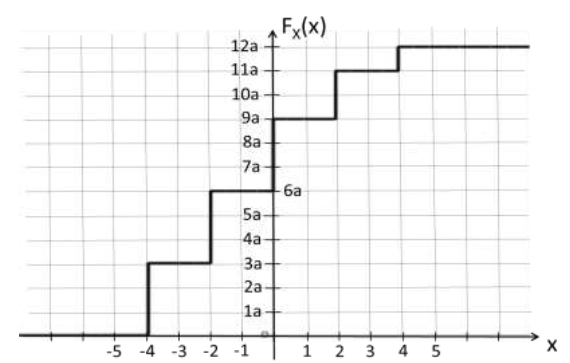

## 1.1 GYLDIG FORDELINGSFUNKTION

For at bestemme om $F_{X\left(x\right)}$er en gyldig fordeligsfunktion anvendes, at 


$$\underset{x\to \infty }{\mathrm{lim}} F_X \left(x\right)=1$$


Det antages at outputtet af fordelingsfunktione ikke antager værdier større end 12a, der gælder følgende.


$$\underset{x\to \infty }{\mathrm{lim}} F_X \left(x\right)=12a$$


Dermed givet det, at


$$a=\frac{1}{12}$$


Fordelingsfunktionen er dermed gældende for værdien af $a$ leg med $\frac{1}{12}$.

## 1.2 TÆTHEDSFUNKTION

For at bestemme tæthedsfunktione $f_X \left(x\right)$anvendes, at størrelse af trinene i fordelingsfunktion er tæthedsfunktionen. Dermed opnåes, at


$$f_X \left(x\right)=\left\lbrace \left\lbrack \begin{array}{cc}
3a & x=-4\\
3a & x=-2\\
3a & x=0\\
2a & x=2\\
1a & x=4\\
0 & \mathrm{ellers}
\end{array}\right\rbrack \right\rbrace$$


## 1.3 MIDDELVÆRDI

For at bestemme middelværdien anvendes, at


$$\bar{X} =E\left\lbrack X\right\rbrack =\sum_{i=1}^n x_i \cdot f_X \left(x_i \right)$$


a = 1/12;

X = [-4, -2, 0, 2, 4];
P = [3*a, 3*a, 3*a, 2*a, 1*a];

EstimationX = 0;

for n = 1:length(P)
    EstimationX = EstimationX + (X(n) * P(n));
end

sym(EstimationX)

$$ans = -\frac{5}{6}$$

Middelværdien er dermed bestemt til at være $-\frac{5}{6}\ldotp$

## 1.4 VARIANS

For at bestemme variansen anvendes, at


$$\mathrm{Var}\left(X\right)=\sigma_x^2 =E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


EstimationXSquared = 0;

for n = 1:length(P)
    EstimationXSquared = EstimationXSquared + (X(n)^2 * P(n));
end

VarianceX = EstimationXSquared - EstimationX^2

VarianceX = 6.3056

Variansen er dermed bestemt til at være 6.3056.

# **2 SANDSYNLIGHED**

I juni måned (30 dage) regner det i gennemsnit 20% af dagene i den første halvdel af måneden og 30% af dagene i den sidste halvdel af måneden.

$A:\mathrm{REGN}$ - $\overline{A} :\mathrm{IKKE}\;\mathrm{REGN}$

$B:1\ldotp \mathrm{HALVDEL}$ - $\overline{B} :2\ldotp \mathrm{HALVDEL}$


$$P\left(A|B\right)=0\ldotp 2$$



$$P\left(A|\overline{B} \right)=0\ldotp 3$$



$$P\left(B\right)=P\left(\overline{B} \right)=0\ldotp 5$$


## **2.1 ANTAL DAGE**

Først findes den totale sandsynlighed for A, givet ved


$$P\left(A\right)=P\left(A|B\right)\cdot P\left(B\right)+P\left(A|\overline{B} \right)\cdot P\left(\overline{B} \right)$$


DaysInMonth = 30;

AGivenB = 0.2;
AGivenNotB = 0.3;
B = 0.5;

NotB = 0.5;

A = AGivenB * B + AGivenNotB * NotB;
DaysWithRain = A * 30

DaysWithRain = 7.5000

Dermed er det bestemt at der regner i gennemsnit 7.5 i juni måned.

## 2.2 BETINGET SANDSYNLIGHED

For at bestemme sandsynligheden for at være i den sidste del af måneden givet at der er regnvejr anvendes, at


$$P\left(\overline{B} |A\right)=\frac{P\left(A|\overline{B} \right)\cdot P\left(\overline{B} \right)}{P\left(A\right)}$$


NotBGivenA = (AGivenNotB * B) / A

NotBGivenA = 0.6000

Dermed er sandsynligheden bestemt til at være 0.6 altså 60%.

## 2.3 REGN HØJST EN DAG

For at bestemme sandsynligheden for højst en dag med regnes observeres, at 


$$P\left(\mathrm{dage}\le 1|B\right)=P\left(0\;\mathrm{dage}\;|\;B\right)+P\left(1\;\mathrm{dag}|B\right)$$


Dertil anvendes ikke sorteret rækkefølge uden tilbagelægning. Succes ses som


$$P\left(A|B\right)=p=0\ldotp 2$$


hvor fiasko ses som 


$$P\left(\overline{A} |B\right)=1-p=0\ldotp 8$$


Sandsynligheden kan bestemmes som 


$$P\left(k\right)=\frac{n!}{k!\cdot \left(n-k\right)!}p^k q^{{\;}^{n-k} }$$


DaysWithinHalfMonth = DaysInMonth / 2;

Bernoulli = @(k, n) (factorial(n) / (factorial(k) * factorial(n-k))) * (AGivenB^k) * ((1-AGivenB)^(n-k));

Bernoulli(1, 15) + Bernoulli(0, 15)

ans = 0.1671

Dermed er sandsynligheden for regn højst en dag bestemt til at være 0.1671 altså 16.71%.

# **3 STOKASTISK PROCESS**

En kontinuert stokastisk process $X\left(t\right)$givet ved


$$X\left(t\right)={\left(-1\right)}^n +W$$


hvor W er i.i.d. Gaussisk fordelte stokastiske variable W ~ N(0, 0.25) og n uafhængigt kan antage værdierne 0 og 1 med lige stor sandsynlighed.�(0; 0,25), og n uafhængigt kan . 

##  3.1 REALISERING

Skitsering af realiseringen laves i matlab.

t = 0:1:5;

mu = 0;
sigma = sqrt(0.25);

Realisation = [[],[],[]];

randi([0, 1])

ans = 1


for n = 1:3
    Realisation(n, :) = (-1)^(randi([0, 1])) + (ones(1, length(t)) * (sigma * randn + mu) - 2) 
end

Realisation =    -1.0867   -1.0867   -1.0867   -1.0867   -1.0867   -1.0867


Realisation =    -1.0867   -1.0867   -1.0867   -1.0867   -1.0867   -1.0867
   -2.5680   -2.5680   -2.5680   -2.5680   -2.5680   -2.5680


Realisation =    -1.0867   -1.0867   -1.0867   -1.0867   -1.0867   -1.0867
   -2.5680   -2.5680   -2.5680   -2.5680   -2.5680   -2.5680
   -0.9000   -0.9000   -0.9000   -0.9000   -0.9000   -0.9000


## 3.2 MIDDEL OG VARIANS AF REALISERING

## 3.3 ENSEMBLE MIDDELVÆRDI OG VARIANS

## 3.4 PROCESSEN